# Train a Deep Neural Network to Invert a Pendulum Using Reinforcement Learning

In this example, we will train a deep neural network using reinforcement learning to invert a pendulum and balance it. The reinforcement learning algorithm we use is called Deep Q-Network (DQN).

## Pendulum Swing Up with image MATLAB Environment

The pendulum we are trying to invert and balance is a simple frictionless pendulum that is initially hanging in a downward position. The training goal is to make the pendulum stand upright without falling over while using as little control effort as possible. 

The control effort in this case is a torque applied at the point from which the pendulum is hanging.

The pendulum dynamics are modeled in MATLAB. This includes its weight, length, and the equations governing its motion under a torque.

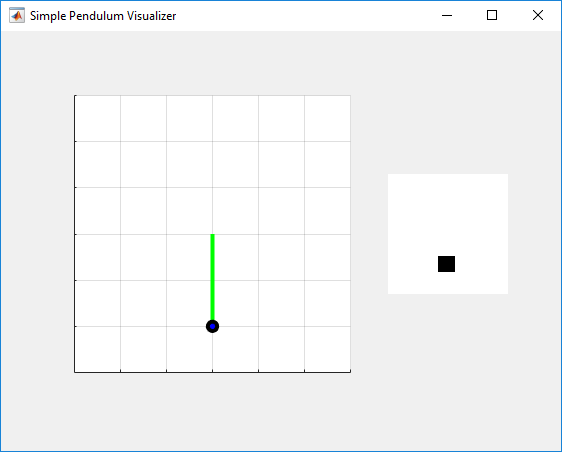

From this point on, we will refer to the model of the pendulum as the "**environment model**". This MATLAB based environment model makes a few assumptions :

- The upward balanced pendulum position is '0' (zero) radians, and the downard hanging position is '`pi'` radians.

- The torque action signal from the agent to the environment can be one of five possible values: [`-2 -1 0 1 2]` Nm.

- The observations from the environment are the simplified grayscale image of the pendulum, and the pendulum angle derivative.

clear
addpath(genpath(pwd))

## Initialize the Environment Model Interface for the Pendulum

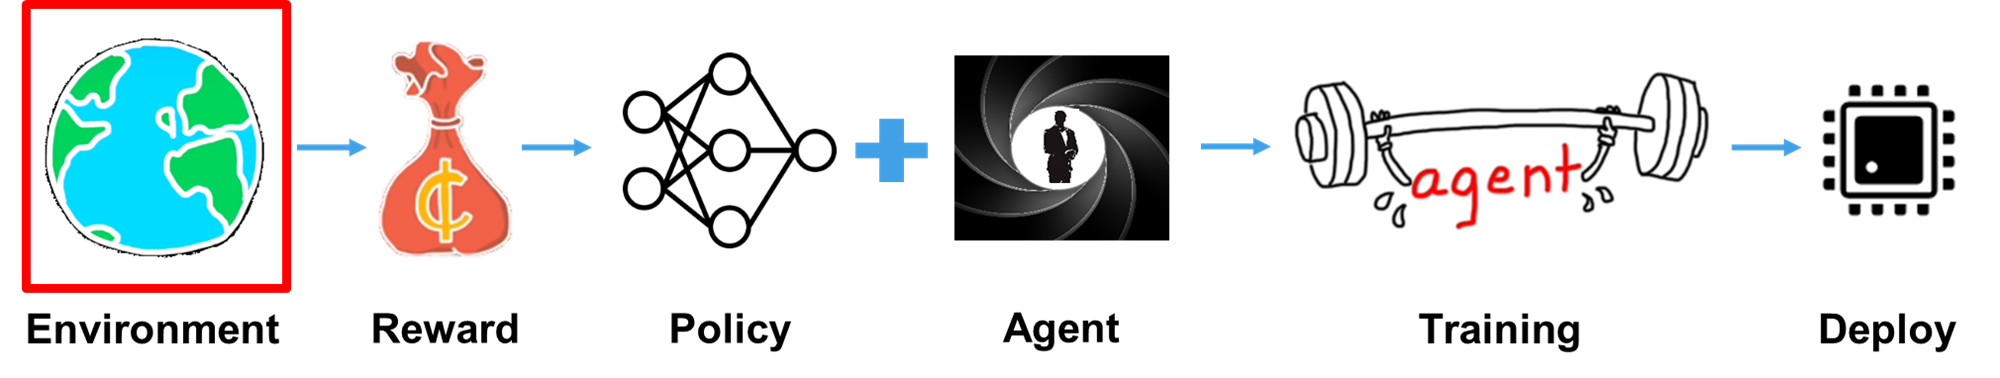

The code snippet below creates an interface to the environment model of the pendulum. We are using one of the many pre-defined environment models available in MATLAB. 

You can see the characteristics of this environment (i.e. the pendulum) when you evaluate the snippet. The "**state**" of the environment will be the position of the pendulum at any point in time.

env = rlPredefinedEnv('SimplePendulumWithImage-Discrete')
plot(env);

The environment model interface provides two "**observations"** at each time step. These observations are meant to represent the state of the environment and are used in the training process. 

The first observation is a 50x50 grayscale image named `"pendImage"`. This image depects the position of the pendulum in terms of an image.

obsInfo = getObservationInfo(env);
obsInfo(1)

The second observation "angularRate" is the angular velocity of the pendulum. This observation provides us with an idea of how fast the pendulum is swinging.

obsInfo(2)

As we mentioned earlier, the control effort (torque) that can be applied to the pendulum has five possible values: `-2`, -1, `0`, 1 or `2` Nm. The environment interface captures this discrete action space below: 

actInfo = getActionInfo(env)

We also fix the random generator seed for reproducibility.

rng(0);

## Define a Reward Signal

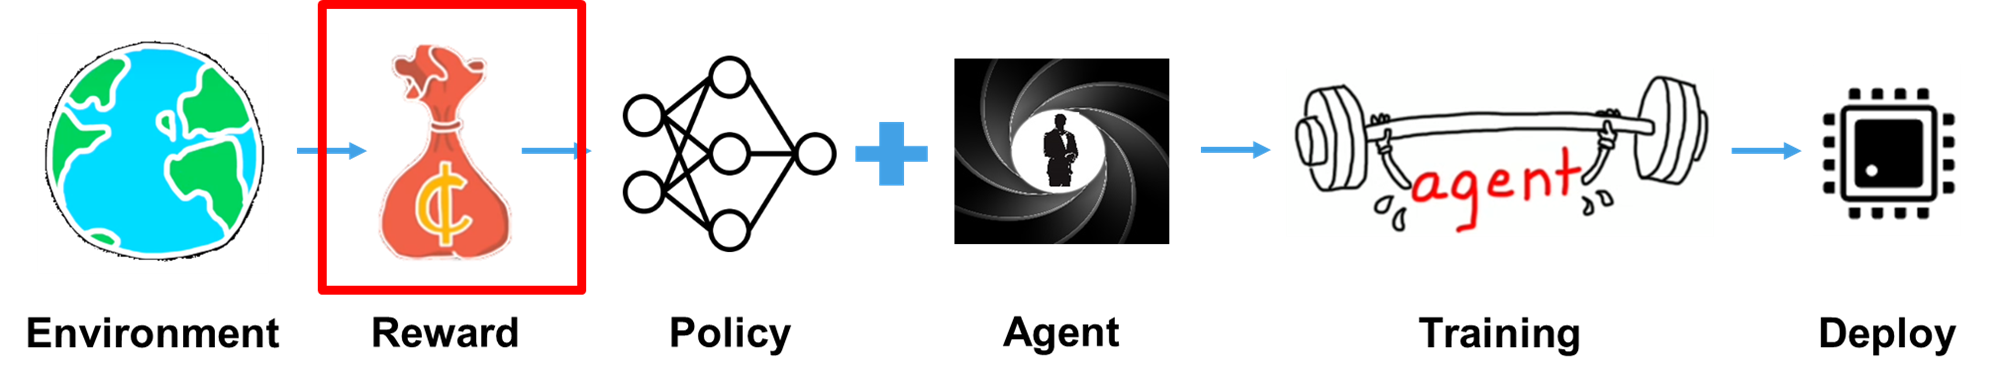

The reward $r_t$, provided at every timestep, is:

###                                                            
$$r_t =-\left({\theta_t }^2 +0\ldotp 1*{\dot{\theta_t } }^2 +0\ldotp 001*{u_{t-1} }^2 \right)$$


where:

- $\theta_t$ is the angle of displacement from the upright position

- $\dot{\theta_t }$ is the derivative of the displacement angle

- $u_{t-1}$ is the torque exterted by the controller effort in the previous time step.

**This reward signal has already been provided in the predefined environment model implemented in the previous section.**

## Define a Deep Neural Network That Will Be Trained Using Reinforcement Learning

In this example, a deep neural network is trained to pick an action at each time step such that the long-term reward from that point of time onwards is maximized.

What this means is that at each time step:

- Given a certain state of the pendulum in terms of its position and how fast it is moving (***observations***), and 

- Given the torque value we have applied in the previous time step (***action***), 

- The deep neural network will ***output*** the next action that provides the maximum ***long-term reward***.

This training will be done by the DQN algorithm, a type of reinforcement learning algorithm

The deep neural network accepts ***three inputs*** (the ***2 observations*** and the ***previous action***) and returns ***one output*** (the next action). This output will be one of the 5 possible torque values [`-2`, -1, `0`, 1 and `2` Nm].

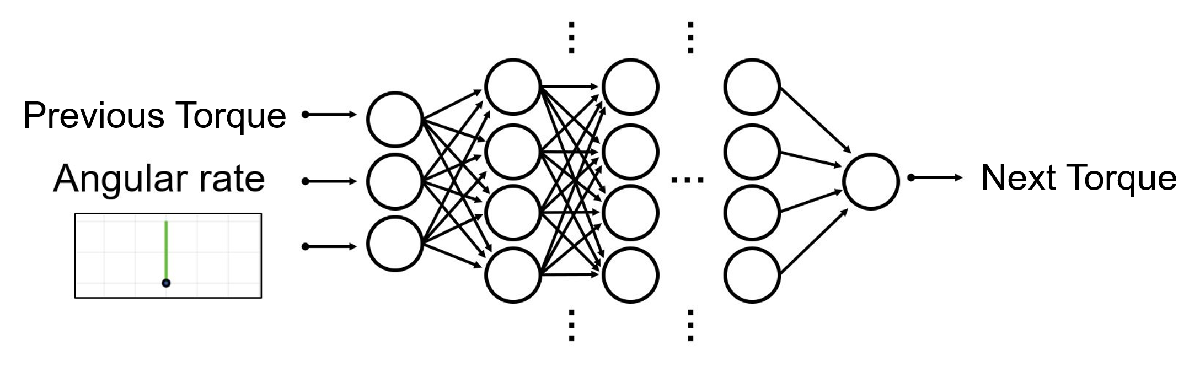

## Contruct the Deep Neural Network with the Deep Network Designer app

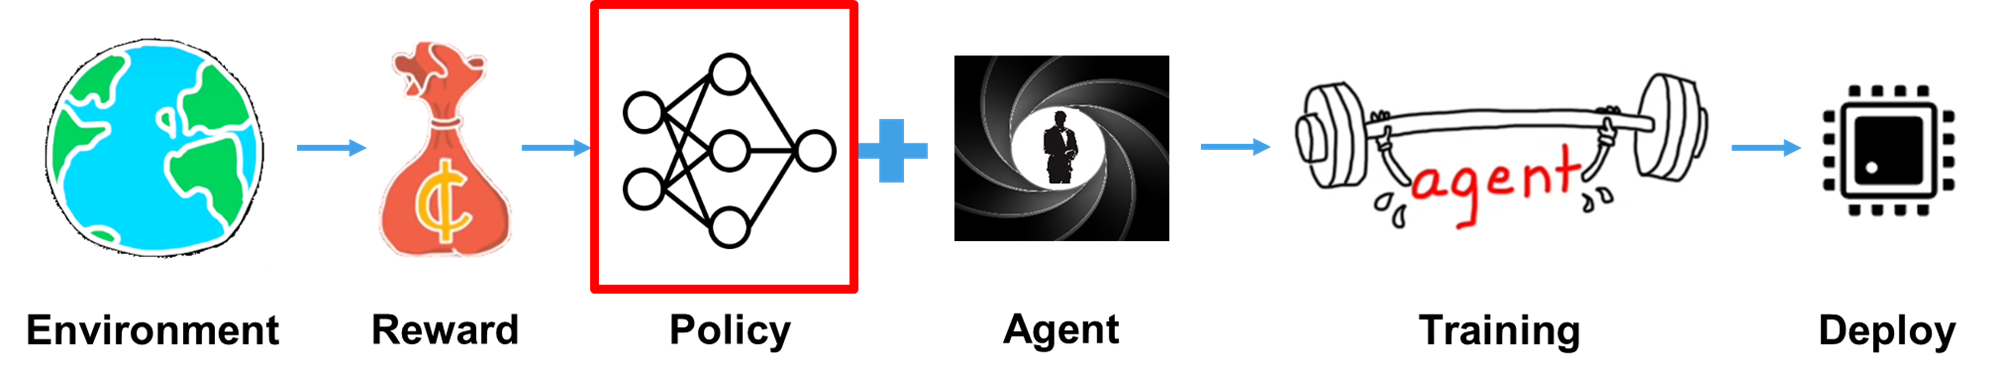

The deep neural network will have 3 paths:

- an image observation path that takes the 50x50 grayscale image as an input

- an angular velocity observation path that takes the 1x1 angular velocity value as an input

- an action path that takes the 1x1 torque value as an input

These paths are then added together to create the output value that represents the torque applied at the base of the pendulum

## Exercise: Complete Defining the 3 Paths in the Deep Network Designer App

### Complete the Action and Angular Velocity Action Paths and Connect them to the Output Path

Load the incomplete deep neural network representation in terms of its layers.

load('lgraph_incomplete.mat');
deepNetworkDesigner;

You will see that the image path has already been completed for you.

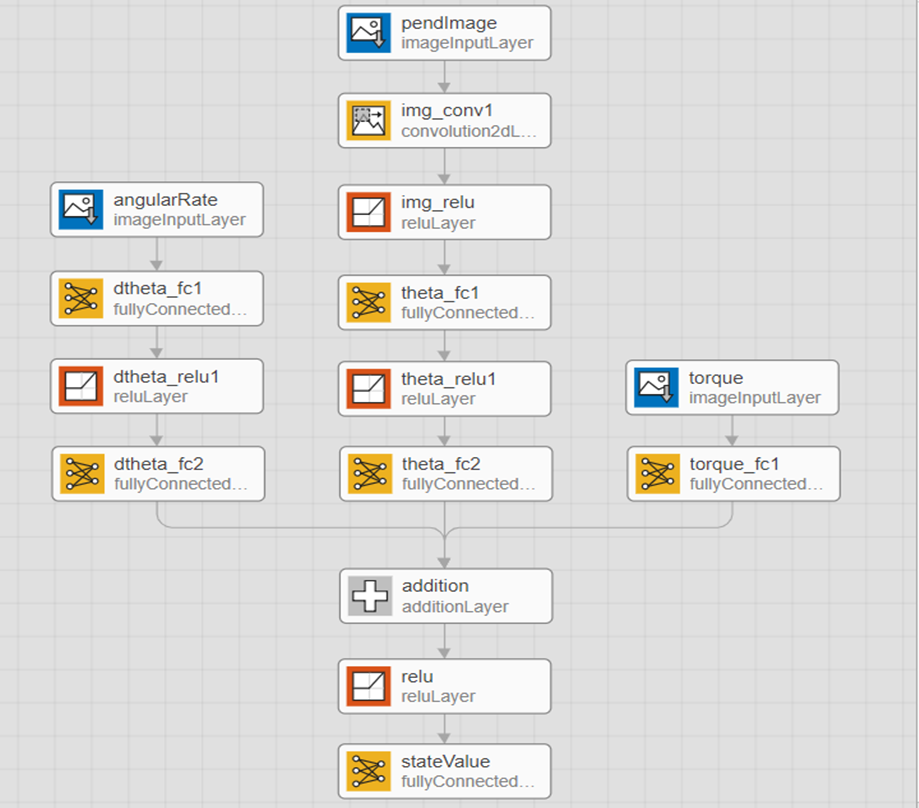

Construct the other 2 input paths for Action and Angular Velocity, and the output path for torque using the following guidelines:

Angular Velocity Path (scalar input)

- `ImageInputLayer: InputSize = 1,1; Normalization = none; ``[ALREADY PRESENT]`

- `FullyConnectedLayer: OutputSize = 400`

- `ReLULayer`

- `FullyConnectedLayer: OutputSize = 300`

Action Path (scalar input) 

- `ImageInputLayer: InputSize = 1,1; Normalization = none; ``[ALREADY PRESENT]`

- `FullyConnectedLayer: OutputSize = 300`

Output Path:

- `AdditionLayer: `Connect the output of all inputs path to the input of this layer. `[ALREADY PRESENT]`

- `ReLULayer ``[ALREADY PRESENT]`

- `FullyConnectedLayer: OutputSize = 1 `for the scalar long term reward value.

## Export Network from Deep Network Designer

To export the network to the workspace, return to the Deep Network Designer and click **Export**. The Deep Network Designer exports the network to a new variable containing the network layers.

Alternatively, click **Generate Code** under **Export** to generate equivalent MATLAB code of the network.

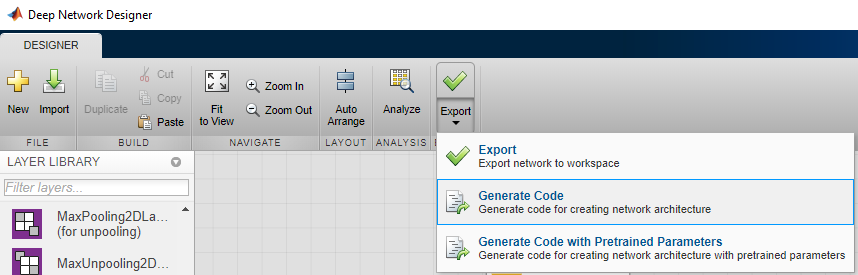

Insert the generated code below and name the final layer graph as "**lgraph**". 

% INSERT GENERATED CODE HERE
%
%
% lgraph = ???


% If using firefox or edge, run the line of code below:
% load("lgraph_MAT.mat");

## Defining a Reinforcement Learning Agent

### 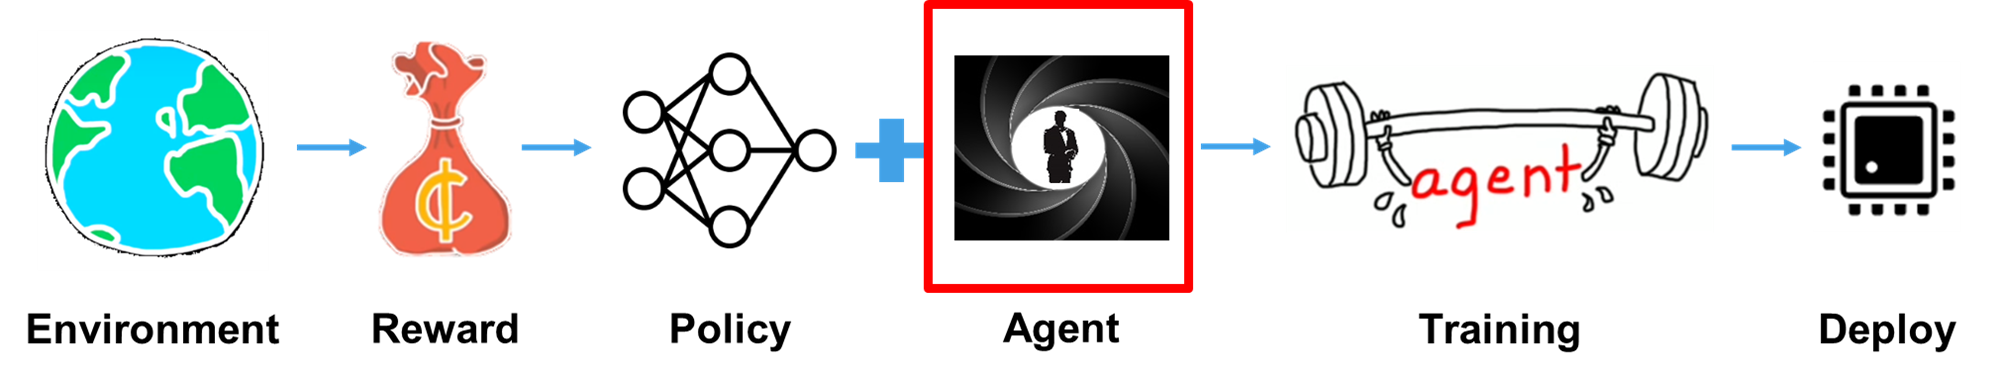

### Agent Definition

A reinforcement learning agent consists of a "**policy"** that is used to determine the next action to take, and an algorithm that trains this policy. 

In this example, we have already defined the structure of a deep neural network that acts as the policy. The next step is to choose the reinforcement learning algorithm (DQN in our case) and set other training options.

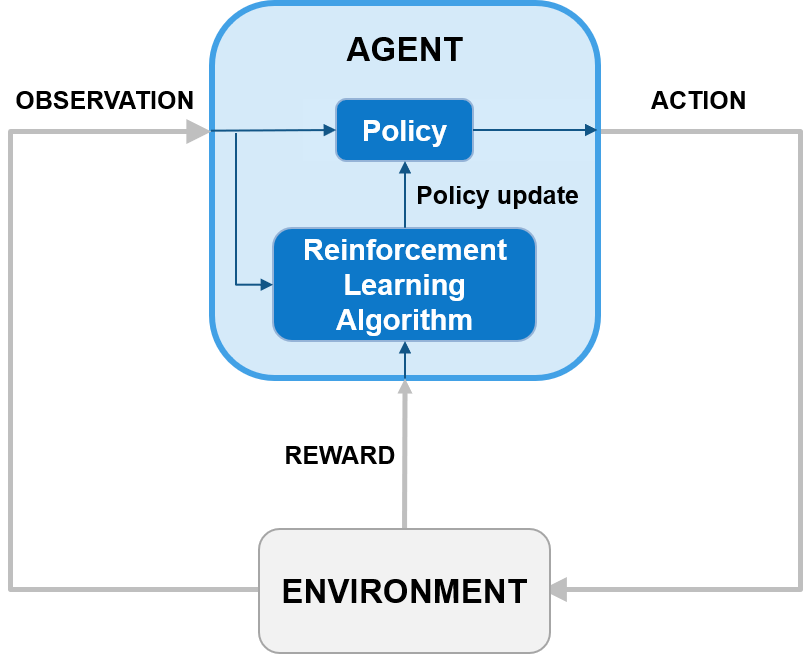

### Set Policy Options

The code below sets some training options for the policy that is represented by the deep neural network we designed in the app ("lgraph").

policyOpts = rlRepresentationOptions('LearnRate',1e-03,'GradientThreshold',1);
policy = rlRepresentation(lgraph,policyOpts,'Observation',{'pendImage','angularRate'},obsInfo,'Action','torque',actInfo);

### Set Reinforcement Learning Algorithm Options

The algorithm we will be using for our agent is called the Deep Q-Network algorithm. A simple way to understand the reasoning behind this name is that it trains a deep neural network to estimate the Q-value we discussed previously.

The script below sets various training and agent hyperparameters.

agentTrainingOptions;

### Create An Agent By Combining The Deep Neural Network Policy With The DQN Algorithm

Use the "**policy**" you have defined and combine it with the algorithm options created above to create an "**agent**". For more information, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

agent = rlDQNAgent(policy,agentOpts);

## Train Agent - 1st Attempt

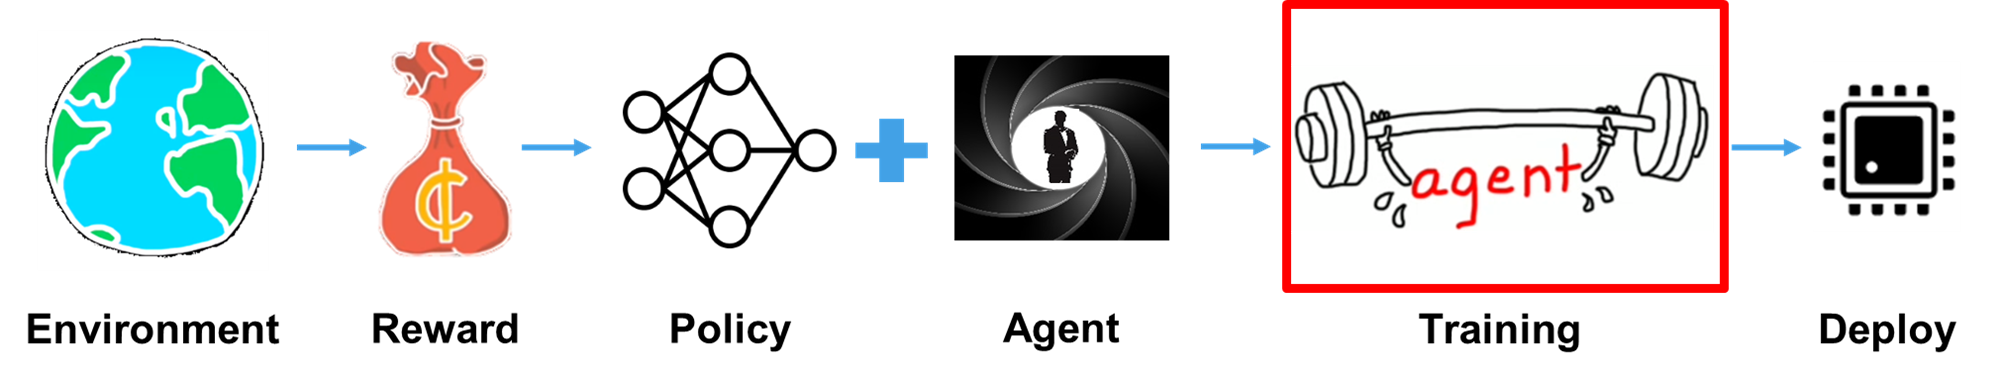

Train the agent using the [train](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This is a computationally intensive process that can take several hours to complete, but we will only run it for a short time today.

plot(env);
train(agent,env,trainOpts)

Wait for a few training episodes to complete. Over the course of these episodes, you will see the deep neural network try to invert the pendulum but fail. It will be able to swing it back and forth, but never swing it above the horizontal axis.

Consequently, the reward value will be very low in these early stages.

You can now stop training by clicking on the "**Stop Training**" button.

## Train Agent - 2nd Attempt

This time, train the agent using the a partially trained agent that has already been trained for 135 episodes. You will be able to clearly see the difference between how the deep neural network tries to invert the pendulum now versus what it was trying before.

load('MATLABPendImageDQN_Partial.mat','agent');
trainingStats = train(agent,env,trainOpts);

## Load Fully Trained Agent

Load a  fully trained agent and then simulate it with the pendulum model to see how quickly and efficiently it inverts and balances the pendulum,

% Load pretrained agent for the example.
load('MATLABPendImageDQN.mat','agent');

The chart below shows the training progress for the fully trained deep neural network that acts as a policy.

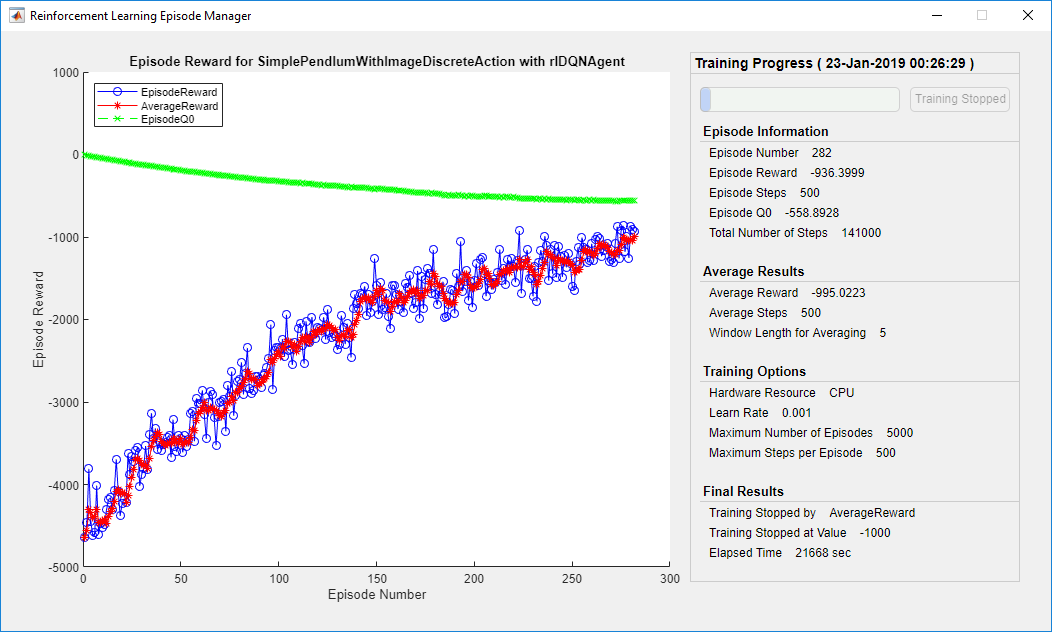

And the snippet below shows how it performs after training.

simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env,agent,simOptions);
totalReward = sum(experience.Reward)

## Conclusion

In this example, we trained a deep neural network to invert and balance a simple pendulum. 

The pendulum was modeled in MATLAB (**environment**) and this model provided image data and angular velocity data that was representative of the pendulum's position (**state/observation**). We then trained a deep neural network to use these obervations to pick a torque value (**action**) based on the long term **reward** of taking that action. This deep neural network  is called a **policy **and it evaluates multiple actions to picks the action which is able to invert and balance the pendulum.

**Disclaimer:**

In this example, we have intentionally not distinguished betwen actors and critics, and also not described the ways in which policy and value functions can be defined. You can read more about that [here](https://www.mathworks.com/help/reinforcement-learning/ug/create-policy-and-value-function-representations.html).

*Copyright 2018-2019 The MathWorks, Inc.*

*MATLAB and Simulink are registered trademarks of The MathWorks, Inc. Please see* [*www.mathworks.com/trademarks*](https://www.mathworks.com/trademarks) *for a list of other trademarks owned by The MathWorks, Inc. Other product or brand names are trademarks or registered trademarks of their respective owners.*